## encoding sequence length v.s. deblurring performance

% 双柱状图绘制模板
% 公众号：阿昆的科研日常

%% 数据准备
% 读取数据
% 自变量
psnr_v = [21.02 21.67 21.83 22.54];
ssim_v = [0.6471 0.6641 0.6780 0.7058];
data_n = length(psnr_v)

data_n = 4

X = 1:data_n;
% 因变量
bar1 = [psnr_v',zeros(data_n,1)];
bar2 = [zeros(data_n,1),ssim_v'];

%% 图片尺寸设置（单位：厘米）
figureUnits = 'centimeters';
figureWidth = 12;
figureHeight = 8;

%% 窗口设置
figureHandle = figure;
set(gcf, 'Units', figureUnits, 'Position', [0 0 figureWidth figureHeight]); % define the new figure dimensions
hold on

%% 颜色定义
% addcolor函数获取方式：
% 公众号后台回复：morecolor
C1 = [230, 84, 0]/255; %255 127 0
C2 = [40, 124, 200]/255;

%% 定义左轴
yyaxis left
GO1 = bar(X,bar1,1,'EdgeColor','k','FaceColor',C1);
hYLabel1 = ylabel('PSNR (dB)');
set(gca,  'YColor', [.1 .1 .1],...         % 坐标轴颜色
          'YTick', 16:2:26,...        % 刻度位置、间隔
          'Ylim' ,[16 26],...            % 坐标轴范围
          'Yticklabel',16:2:26)   % Y坐标轴刻度标签
% 数值标注
for n = 1:data_n
    text(n-0.35,psnr_v(n)+0.5,num2str(psnr_v(n)),'FontSize',8);
end


%% 定义右轴
yyaxis right
GO2 = bar(X,bar2,1,'EdgeColor','k','FaceColor',C2);
hYLabel2 = ylabel('SSIM');
set(gca, 'YColor', [.1 .1 .1],... 
         'YTick', 0.2:0.1:0.8, ...
         'Ylim' ,[0.2 0.8], ...
         'Yticklabel',0.2:0.1:0.8)
% 数值标注
for n = 1:data_n
    text(n-0.05,ssim_v(n)+0.025,num2str(ssim_v(n),"%.4f"),'FontSize',8);
end
     
%% X轴与其它细节调整
xlabel("Length of the encoding sequence"), 
set(gca, 'Box', 'off', ...                                         % 边框
         'XGrid', 'off', 'YGrid', 'on', ...                        % 网格
         'TickDir', 'out', 'TickLength', [.01 .01], ...            % 刻度
         'XMinorTick', 'off', 'YMinorTick', 'off', ...             % 小刻度
         'XColor', [.1 .1 .1],...                                  % 坐标轴颜色
         'Xticklabel',{'8' '16' '32' '64' })  % X轴标签
  
         
%% Legend设置和调整
hLegend = legend([GO1(1),GO2(2)], ...
    'PSNR', 'SSIM', ...
    'Location', 'northwest','orientation','horizontal', 'FontSize', 7)

hLegend =   Legend (PSNR, SSIM) - 属性:

         String: {'PSNR'  'SSIM'}
       Location: 'northwest'
    Orientation: 'horizontal'
       FontSize: 7
       Position: [0.1540 0.8377 0.3342 0.0529]
          Units: 'normalized'

  显示 所有属性


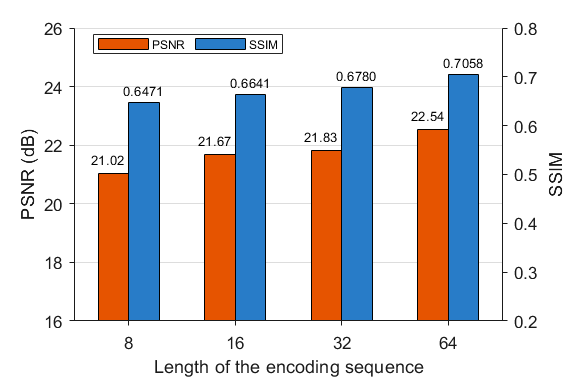


P = hLegend.Position;
hLegend.Position = P + [0.01 0.02 0 0];

% legend_adjust(hLegend, 6, 2)

%% 刻度标签字体和字号
set(gca, 'FontName', 'Helvetica', 'FontSize', 10)

%% 排版导出
figW = figureWidth;
figH = figureHeight;
set(figureHandle,'PaperUnits',figureUnits);
set(figureHandle,'PaperPosition',[0 0 figW figH]);
fileout = 'abexp_ce_len';
% print(figureHandle,[fileout,'.png'],'-r600','-dpng');
print(figureHandle,[fileout,'.pdf'],'-r600','-dpdf');